clear
format shortG
warning off;
load fisheriris

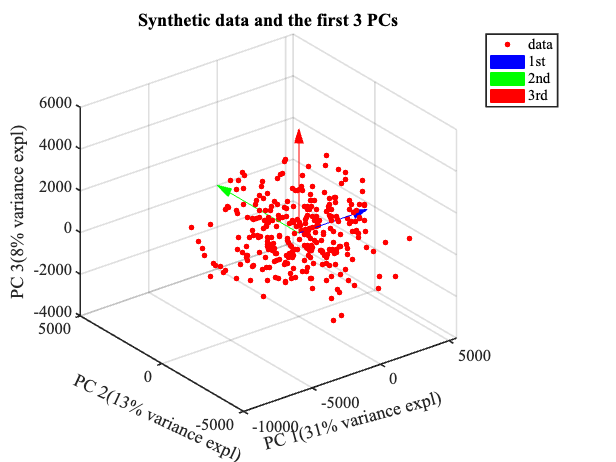

% data prep
inputs_ori = readtable('syn_2.csv');% data 6
inputs_ori = inputs_ori(1:300,1:end-1);
inputs_ori = table2array(inputs_ori);
inputs_ori = str2double(inputs_ori);
inputs = inputs_ori-mean(inputs_ori);

[coeff_real,~,~,~,explained_1,~] = pca(inputs);
o = [0 0 0];
final_all_data = [inputs;coeff_real(:,1)';coeff_real(:,2)';coeff_real(:,3)'];
[coeff1,~,~,~,explained,~] = pca(final_all_data);
Z=final_all_data*coeff1(:,1:3);
%Z = round(Z,4);
coeff_real = round(coeff_real,2);
explained = round(explained);


figure;
view(3)
hold on
plot3(Z(1:end-3,1),Z(1:end-3,2),Z(1:end-3,3),'r.','MarkerSize',15)
arrow(o,Z(end-2,:)*5000,'Color','b');
arrow(o,Z(end-1,:)*5000,'Color','g');
arrow(o,Z(end,:)*5000,'Color','r');
xlabel('PC 1(' + string(explained(1))+"% variance expl)")
ylabel('PC 2(' + string(explained(2))+"% variance expl)")
zlabel('PC 3(' + string(explained(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
title('Synthetic data and the first 3 PCs')
legend('data','1st','2nd','3rd')
set(gca, 'FontSize', 15);% Increase font size
set(gca, 'LineWidth', 1.5); % Make lines thicker
set(gca, 'FontName', 'Times New Roman'); % Set preferred font
grid on
grid on
hold off

% generate synaptic weights
SetRNG(1);
dim = size(inputs,2);
n_src = dim;
n_dst = 600;
n_per_src = round(n_src*0.4);
synaptic_weights_mat = randn(n_src,n_dst);
[srcIdx,dstIdx] = ConnectHypergeometric(n_dst, n_src, n_per_src);
index = [srcIdx;dstIdx];
for i = 1:n_dst;
    nonzero_idx = index(2,find(index(1,:) == i));
    zero_idx = setdiff(1:n_src,nonzero_idx);
    synaptic_weights_mat(zero_idx,i) = 0;
end
cells = synaptic_weights_mat; %original

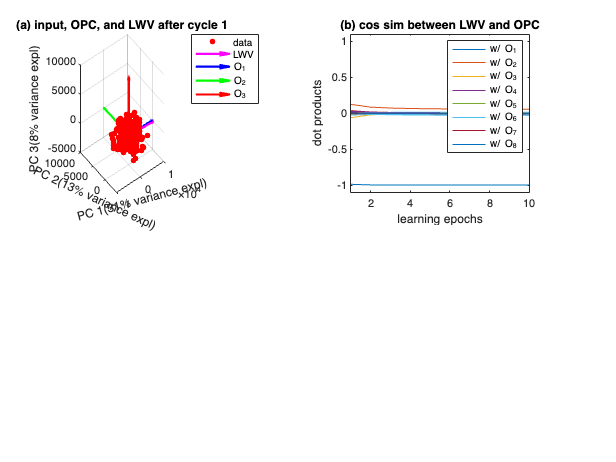

%cycle 1, find the first PC
cycle = 1;
ori_cycle1_cells = cells;
mean_sum = [];
final_weight = [];
epoch = 400;


%sum1 = [];
%test1 = [];
mean1 = [];
for e = 1:epoch;
    imterim_weight = [];
    sampled_data = inputs;
    sampled_data = inputs(randperm(size(inputs, 1)),:);
    mean_sum = [];
    for col = 1:size(sampled_data,1); % loop over all inputs
        lr = 0.0001;
        input1_ori = sampled_data(col,:);% each input
        input1 = input1_ori';
        product = input1'*ori_cycle1_cells;
        signs = sign(product);
        winning_idx = 1:length(product);
        %winning_idx = winning_idx(randperm(length(winning_idx)));
        winning_cell = ori_cycle1_cells(:,winning_idx); % the winning cell set, which may contain more than one winning cell
        update_winner_ori = winning_cell+(signs.*input1-winning_cell)*lr;
        %mean_sum = [mean_sum,signs.*input1];
        update_winner_norm = update_winner_ori;
        ori_cycle1_cells(:,winning_idx) = update_winner_norm;
    end
     final_weight = [final_weight,normc(ori_cycle1_cells(:,1))];
end

bench_v = ones(size(update_winner_norm,1),1);
id = find(sign(bench_v'*normc(update_winner_norm)) == 1);
center1 = normc(mean(update_winner_norm(:,id),2));
%center1 = normc(update_winner_norm(:,end));%normc(mean(update_winner_norm,2));
center1 = round(center1,2);

w1_real = round(normc(center1)'*normc(coeff_real),2);
%mean1(:,end)'*normc(coeff_real)

final_all_data = [inputs;center1';coeff_real(:,1)';coeff_real(:,2)';coeff_real(:,3)';];
[coeff_c1,~,~,~,explained,~] = pca(final_all_data);
Z=final_all_data*coeff_c1(:,1:3);
%Z = round(Z,4);
explained = round(explained);


index = round(linspace(1,epoch,400));
result_c1 = final_weight(:,index);
training_dot = normc(final_weight)'*normc(coeff_real);


figure;
subplot(2,2,1)
view(3)
hold on
plot3(Z(1:end-4,1),Z(1:end-4,2),Z(1:end-4,3),'r.','MarkerSize',15)
quiver3(0,0,0,Z(end-3,1)*10000,Z(end-3,2)*10000,Z(end-3,3)*10000,0,'m','LineWidth',2);
quiver3(0,0,0,Z(end-2,1)*10000,Z(end-2,2)*10000,Z(end-2,3)*10000,0,'b','LineWidth',2);
quiver3(0,0,0,Z(end-1,1)*10000,Z(end-1,2)*10000,Z(end-1,3)*10000,0,'g','LineWidth',2);
quiver3(0,0,0,Z(end,1)*10000,Z(end,2)*10000,Z(end,3)*10000,0,'r','LineWidth',2);
title('(a) input, OPC, and LWV after cycle 1')
legend('data','LWV','O_1','O_2','O_3')
xlabel('PC 1(' + string(explained(1))+"% variance expl)")
ylabel('PC 2(' + string(explained(2))+"% variance expl)")
zlabel('PC 3(' + string(explained(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off


subplot(2,2,2)
plot(training_dot)
title('(b) cos sim between LWV and OPC')
legend('w/ O_1','w/ O_2','w/ O_3','w/ O_4','w/ O_5','w/ O_6','w/ O_7','w/ O_8')
xlabel('learning epochs')
ylabel('dot products')
ylim([-1.1 1.1])
xlim([1 10])

%training_dot = array2table(training_dot,'VariableNames', {'pc1', 'pc2','pc3','pc4'})


new_weight = update_winner_norm-mean(update_winner_norm,2);
new_weight = normc(new_weight)';
[idx,C,sumd,D] = kmeans(new_weight,2);
[coeff_c,~,~,~,explained,~] = pca([new_weight;C]);


Z_c1 = [new_weight;C]*coeff_c(:,1:3);

line11_real = abs(round(normr(C(1,:))*normc(coeff_real),2))

line11_real =             1         0.03         0.01         0.01         0.02         0.03            0         0.01         0.01         0.01         0.01            0         0.01            0         0.01            0         0.01            0            0         0.01            0            0            0            0         0.01            0            0            0         0.01            0            0         0.01            0         0.01         0.01            0         0.01            0            0         0.01         0.01            0            0            0         0.01            0            0         0.01         0.01            0


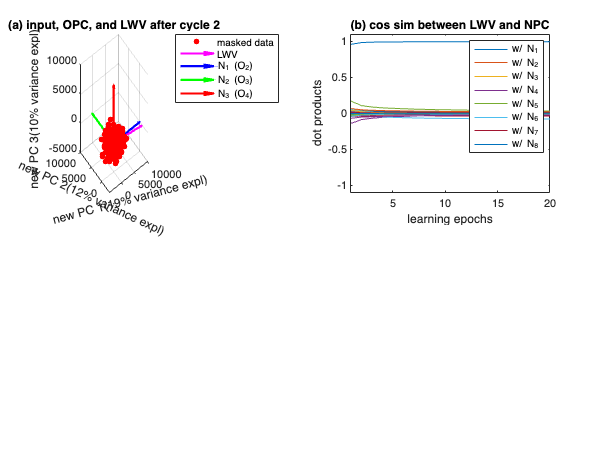

%cycle 2 input masking

norm_vec_c1 = normc(center1);
%norm_vec_c1 = coeff_real(:,1);
c2_inputs_set = (inputs'-norm_vec_c1*(inputs*norm_vec_c1./norm(norm_vec_c1))')';
c2_inputs_set = c2_inputs_set-mean(c2_inputs_set); % new data


[coeff_c2,~,~,~,explained,~] = pca(c2_inputs_set);
o = [0 0 0];

final_all_data = [c2_inputs_set;coeff_c2(:,1)';coeff_c2(:,2)';coeff_c2(:,3)'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Z=final_all_data*coeff(:,1:3);
explained = round(explained);

normc(coeff_c2(:,1))'*normc(coeff_real);
normc(coeff_c2(:,2))'*normc(coeff_real);
normc(coeff_c2(:,3))'*normc(coeff_real);


%cycle 2, find the second PC
cycle = 2;
ori_cycle2_cells = cells;
mean_sum = [];
final_weight = [];
epoch = 400;

sum1 = [];
for e = 1:epoch;
    sampled_data = c2_inputs_set;
    sampled_data = c2_inputs_set(randperm(size(c2_inputs_set, 1)),:);
    for col = 1:size(sampled_data,1); % loop over all inputs
        lr = 0.0001;
        input1_ori = sampled_data(col,:);% each input
        input1 = input1_ori';
        product = input1'*ori_cycle2_cells;
        signs = sign(product);
        sum1 = [sum1;sum(signs)];
        winning_idx = 1:length(product);
        %winning_idx = winning_idx(randperm(length(winning_idx)));
        winning_cell = ori_cycle2_cells(:,winning_idx); % the winning cell set, which may contain more than one winning cell
        update_winner_ori = winning_cell+(signs.*input1-winning_cell)*lr;
        update_winner_norm = update_winner_ori;
        ori_cycle2_cells(:,winning_idx) = update_winner_norm;
    end

    if e>epoch*0.5;
        mean_sum = [mean_sum,mean(update_winner_norm,2)];
    end
     %final_weight = [final_weight,mean(update_winner_norm,2)];
     final_weight = [final_weight,normc(ori_cycle2_cells(:,1))];
end



bench_v = ones(size(update_winner_norm,1),1);
id = find(sign(bench_v'*normc(update_winner_norm)) == 1);
center2 = normc(mean(update_winner_norm(:,id),2));
%center2 = normc(update_winner_norm(:,end));%normc(mean(update_winner_norm,2));
center2 = round(center2,2);

w2_real = round(normc(center2)'*normc(coeff_real),2);
w2_c2 = normc(center2)'*normc(coeff_c2);


final_all_data = [c2_inputs_set;center2';coeff_c2(:,1)';coeff_c2(:,2)';coeff_c2(:,3)';];
[coeff_c,~,~,~,explained,~] = pca(final_all_data);
Z=final_all_data*coeff_c(:,1:3);
explained = round(explained);

index = round(linspace(1,epoch,400));
result_c2 = final_weight(:,index);
training_dot2 = normc(final_weight)'*normc(coeff_c2);

figure;
subplot(2,2,1)
view(3)
hold on
plot3(Z(1:end-4,1),Z(1:end-4,2),Z(1:end-4,3),'r.','MarkerSize',15)
quiver3(0,0,0,Z(end-3,1)*10000,Z(end-3,2)*10000,Z(end-3,3)*10000,0,'m','LineWidth',2);
quiver3(0,0,0,Z(end-2,1)*10000,Z(end-2,2)*10000,Z(end-2,3)*10000,0,'b','LineWidth',2);
quiver3(0,0,0,Z(end-1,1)*10000,Z(end-1,2)*10000,Z(end-1,3)*10000,0,'g','LineWidth',2);
quiver3(0,0,0,Z(end,1)*10000,Z(end,2)*10000,Z(end,3)*10000,0,'r','LineWidth',2);
title('(a) input, OPC, and LWV after cycle 2')
legend('masked data','LWV','N_1 (O_2)','N_2 (O_3)','N_3 (O_4)')
xlabel('new PC 1(' + string(explained(1))+"% variance expl)")
ylabel('new PC 2(' + string(explained(2))+"% variance expl)")
zlabel('new PC 3(' + string(explained(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off


subplot(2,2,2)
plot(training_dot2)
title('(b) cos sim between LWV and NPC')
legend('w/ N_1','w/ N_2','w/ N_3','w/ N_4','w/ N_5','w/ N_6','w/ N_7','w/ N_8')
xlabel('learning epochs')
ylabel('dot products')
ylim([-1.1 1.1])
xlim([1 20])


new_weight = update_winner_norm-mean(update_winner_norm,2);
new_weight = normc(new_weight)';
[idx,C,sumd,D] = kmeans(new_weight,2);
[coeff_c,~,~,~,explained,~] = pca([new_weight;C]);


Z_c2 = [new_weight;C]*coeff_c(:,1:3);


true_2PC = coeff_real(:,1:2);
estimated_2PC = [center1,center2];
true_PC_var = var(inputs*normc(true_2PC))./sum(var(inputs*normc(true_2PC)));
estimated_PC_var = var(inputs*normc(estimated_2PC))./sum(var(inputs*normc(estimated_2PC)));

estimated_PC1 = [center1];
mat_PC1 = repelem(var(inputs*normc(estimated_PC1)),n_dst,1);
mat_PC12 = [mat_PC1,var(inputs*normc(update_winner_norm))'];
max(mat_PC12(:,2)./sum(mat_PC12,2));
min(mat_PC12(:,2)./sum(mat_PC12,2));
%figure;;
%boxplot(rmoutliers(mat_PC12(:,2)./sum(mat_PC12,2)))


line21_real = abs(round(normr(C(2,:))*normc(coeff_real),2))

line21_real =          0.03         0.99         0.08         0.01         0.01         0.02         0.07         0.02         0.03         0.01         0.01         0.02            0         0.01            0         0.02         0.01            0         0.01            0         0.01         0.01         0.01         0.01            0            0         0.02         0.01            0         0.01            0            0            0            0         0.01         0.01            0         0.01            0         0.01            0         0.01         0.01         0.01            0            0            0            0            0         0.01


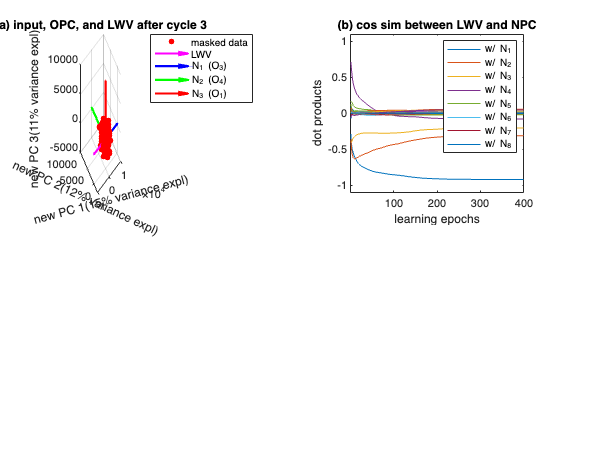

%cycle 3 input masking

norm_vec_c2 = normc(center2);
c3_inputs_set = (c2_inputs_set'-norm_vec_c2*(c2_inputs_set*norm_vec_c2./norm(norm_vec_c2))')';
c3_inputs_set = c3_inputs_set-mean(c3_inputs_set); % new data

[coeff_c3,~,~,~,explained,~] = pca(c3_inputs_set);
o = [0 0 0];
explained = round(explained);
final_all_data = [c3_inputs_set;coeff_c3(:,1)';coeff_c3(:,2)';coeff_c3(:,3)'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Z=final_all_data*coeff(:,1:3);

normc(coeff_c3(:,1))'*normc(coeff_real);
normc(coeff_c3(:,2))'*normc(coeff_real);
normc(coeff_c3(:,3))'*normc(coeff_real);



%cycle 3, find the 3rd PC
cycle = 3;
ori_cycle3_cells = cells;
mean_sum = [];
final_weight = [];
epoch = 400;


for e = 1:epoch;
    sampled_data = c3_inputs_set;
    sampled_data = c3_inputs_set(randperm(size(c3_inputs_set, 1)),:);
    for col = 1:size(sampled_data,1); % loop over all inputs
        lr = 0.0001;
        input1_ori = sampled_data(col,:);% each input
        input1 = input1_ori';
        product = input1'*ori_cycle3_cells;
        signs = sign(product);
        winning_idx = 1:length(product);
        %winning_idx = winning_idx(randperm(length(winning_idx)));
        winning_cell = ori_cycle3_cells(:,winning_idx); % the winning cell set, which may contain more than one winning cell
        update_winner_ori = winning_cell+(signs.*input1-winning_cell)*lr;
        update_winner_norm = update_winner_ori;
        ori_cycle3_cells(:,winning_idx) = update_winner_norm;
    end

    if e>epoch*0.5;
        mean_sum = [mean_sum,mean(update_winner_norm,2)];
    end
     %final_weight = [final_weight,mean(update_winner_norm,2)];
     final_weight = [final_weight,normc(ori_cycle3_cells(:,1))];
end



bench_v = ones(size(update_winner_norm,1),1);
id = find(sign(bench_v'*normc(update_winner_norm)) == 1);
[max_align,id] = max(abs(normc(update_winner_norm)'*coeff_real(:,3)));
%[min_align,id] = min(abs(normc(update_winner_norm)'*coeff_real(:,3)));
center3 = normc(mean(update_winner_norm(:,id),2));
w3_real = normc(center3)'*normc(coeff_real);
w3_c3 = normc(center3)'*normc(coeff_c3);


final_all_data = [c3_inputs_set;center3';coeff_c3(:,1)';coeff_c3(:,2)';coeff_c3(:,3)';];
[coeff_c,~,~,~,explained,~] = pca(final_all_data);
Z=final_all_data*coeff_c(:,1:3);
explained = round(explained);

index = round(linspace(1,epoch,400));
result_c3 = final_weight(:,index);
training_dot3 = normc(final_weight)'*normc(coeff_c3);

figure;
subplot(2,2,1)
view(3)
hold on
plot3(Z(1:end-4,1),Z(1:end-4,2),Z(1:end-4,3),'r.','MarkerSize',15)
quiver3(0,0,0,Z(end-3,1)*10000,Z(end-3,2)*10000,Z(end-3,3)*10000,0,'m','LineWidth',2);
quiver3(0,0,0,Z(end-2,1)*10000,Z(end-2,2)*10000,Z(end-2,3)*10000,0,'b','LineWidth',2);
quiver3(0,0,0,Z(end-1,1)*10000,Z(end-1,2)*10000,Z(end-1,3)*10000,0,'g','LineWidth',2);
quiver3(0,0,0,Z(end,1)*10000,Z(end,2)*10000,Z(end,3)*10000,0,'r','LineWidth',2);
title('(a) input, OPC, and LWV after cycle 3')
legend('masked data','LWV','N_1 (O_3)','N_2 (O_4)','N_3 (O_1)')
xlabel('new PC 1(' + string(explained(1))+"% variance expl)")
ylabel('new PC 2(' + string(explained(2))+"% variance expl)")
zlabel('new PC 3(' + string(explained(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off

subplot(2,2,2)
plot(training_dot3)
title('(b) cos sim between LWV and NPC')
legend('w/ N_1','w/ N_2','w/ N_3','w/ N_4','w/ N_5','w/ N_6','w/ N_7','w/ N_8')
xlabel('learning epochs')
ylabel('dot products')
ylim([-1.1 1.1])
xlim([1 400])

true_3PC = coeff_real(:,1:3);
estimated_3PC = [center1,center2,center3];
true_PC_var = var(inputs*normc(true_3PC))./sum(var(inputs*normc(true_3PC)));
estimated_PC_var = var(inputs*normc(estimated_3PC))./sum(var(inputs*normc(estimated_3PC)));

estimated_PC12 = [center1,center2];
mat_PC12 = repelem(var(inputs*normc(estimated_PC12)),n_dst,1);
mat_PC123 = [mat_PC12,var(inputs*normc(update_winner_norm))'];
max(mat_PC123(:,3)./sum(mat_PC123,2));
min(mat_PC123(:,3)./sum(mat_PC123,2));


% true_PC_var = var(inputs*normc(coeff_real(:,3)))./sum(var(inputs*normc(coeff_real)))
% esti_PC_var = var(inputs*normc(center3))./sum(var(inputs*normc(coeff_real)))

normc(update_winner_norm)'*normc(coeff_c3(:,1));

new_weight = update_winner_norm-mean(update_winner_norm,2);
new_weight = normc(new_weight)';
[idx,C,sumd,D] = kmeans(new_weight,4);
%[C,winner_idx] = SOM(new_weight);
combine_line_data = normr([new_weight;C]);
[coeff_c,~,~,~,explained,~] = pca(combine_line_data);


Z_c3 = [new_weight;C]*coeff_c(:,1:3);


lines = normr(C([2 4],:));
c3_line1 = lines(1,:);
c3_line2 = lines(2,:);
line31_real = abs(round(c3_line1*normc(coeff_real),2))

line31_real =          0.02         0.09         0.99         0.01         0.12         0.06         0.04            0         0.02         0.01         0.01         0.02            0            0         0.02         0.01            0         0.02         0.02         0.03            0         0.01            0         0.01         0.01         0.02            0         0.01         0.01            0         0.01            0            0            0         0.01         0.02         0.01            0         0.01            0         0.01         0.01            0            0            0            0            0            0            0            0


line32_real = abs(round(c3_line2*normc(coeff_real),2))

line32_real =             0         0.02         0.04         0.96         0.28         0.02         0.05         0.01         0.03         0.02         0.02         0.01         0.01         0.01         0.02         0.01         0.01         0.02            0         0.01         0.01         0.01         0.02         0.01         0.02            0         0.01         0.01         0.01            0         0.01         0.01            0            0            0         0.01            0            0         0.01         0.01            0         0.01            0         0.01            0            0         0.01            0            0            0


line3_real_current = round(lines*normc(coeff_c3),2);

true_3PC = coeff_real(:,1:3);
estimated_3PC = [center1,center2,lines(2,:)'];
true_PC_var = var(inputs*normc(true_3PC))./sum(var(inputs*normc(true_3PC)));
estimated_PC_var = var(inputs*normc(estimated_3PC))./sum(var(inputs*normc(estimated_3PC)));

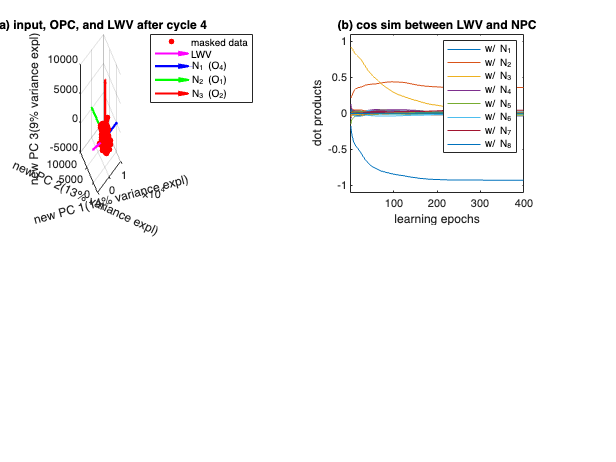

%cycle 4 input masking
center3 = c3_line1'; %modify this to determine which line to inherit from; c3_line1 or c3_line2
norm_vec_c3 = normc(center3);
%norm_vec_c3 = coeff_real(:,3);
c4_inputs_set = (c3_inputs_set'-norm_vec_c3*(c3_inputs_set*norm_vec_c3./norm(norm_vec_c3))')';
c4_inputs_set = c4_inputs_set-mean(c4_inputs_set); % new data


[coeff_c4,~,~,~,explained,~] = pca(c4_inputs_set);
o = [0 0 0];

final_all_data = [c4_inputs_set;coeff_c4(:,1)';coeff_c4(:,2)';coeff_c4(:,3)'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Z=final_all_data*coeff(:,1:3);

normc(coeff_c4(:,1))'*normc(coeff_real);
normc(coeff_c4(:,2))'*normc(coeff_real);
normc(coeff_c4(:,3))'*normc(coeff_real);
explained = round(explained);



% cycle 4, find line 41 and 42
cycle = 4;
ori_cycle4_cells = cells;
final_weight = [];
epoch = 400;

mean1 = [];
for e = 1:epoch;
    sampled_data = c4_inputs_set;
    sampled_data = c4_inputs_set(randperm(size(c4_inputs_set, 1)),:);
    mean_sum = [];
    for col = 1:size(sampled_data,1); % loop over all inputs
        lr = 0.0001;
        input1_ori = sampled_data(col,:);% each input
        %input1 = normr(input1_ori)';
        input1 = input1_ori';
        product = input1'*ori_cycle4_cells;
        signs = sign(product);
        sign2 = sign(input1'*ori_cycle4_cells(:,1));
        winning_idx = 1:length(product);
        %winning_idx = winning_idx(randperm(length(winning_idx)));
        winning_cell = ori_cycle4_cells(:,winning_idx); % the winning cell set, which may contain more than one winning cell
        update_winner_ori = winning_cell+(signs.*input1-winning_cell)*lr;
        update_winner_norm = update_winner_ori;
        mean_sum = [mean_sum,sign2.*input1];
        ori_cycle4_cells(:,winning_idx) = update_winner_norm;
    end
    %mean1 = [mean1,normc(mean(mean_sum,2))];
    mean1 = [mean1,mean(mean_sum,2)];
    final_weight = [final_weight,normc(ori_cycle4_cells(:,1))];
end



bench_v = ones(size(update_winner_norm,1),1);
id = find(sign(bench_v'*normc(update_winner_norm)) == 1);
[max_align,id] = max(abs(normc(update_winner_norm)'*coeff_real(:,4)));
%[min_align,id] = min(abs(normc(update_winner_norm)'*coeff_real(:,4)));
center4 = normc(mean(update_winner_norm(:,id),2));
%center4 = normc(mean(update_winner_norm(:,id),2));
center4 = round(center4,2);
w4_real = normc(center4)'*normc(coeff_real);
w4_c4 = normc(center4)'*normc(coeff_c4);


final_all_data = [c4_inputs_set;center4';coeff_c4(:,1)';coeff_c4(:,2)';coeff_c4(:,3)';];
[coeff_c,~,~,~,explained,~] = pca(final_all_data);
Z=final_all_data*coeff_c(:,1:3);
explained = round(explained);

index = round(linspace(1,epoch,20));
result_c4 = final_weight(:,index);
training_dot4 = normc(final_weight)'*normc(coeff_c4);

ori_line_to_mean = sum(sign(mean1(:,end)'*inputs') == 1)./size(inputs,1);
after_line_to_mean = sum(sign(mean1(:,end)'*mean_sum) == 1)./size(inputs,1);

figure;
subplot(2,2,1)
view(3)
hold on
plot3(Z(1:end-4,1),Z(1:end-4,2),Z(1:end-4,3),'r.','MarkerSize',15)
quiver3(0,0,0,Z(end-3,1)*10000,Z(end-3,2)*10000,Z(end-3,3)*10000,0,'m','LineWidth',2);
quiver3(0,0,0,Z(end-2,1)*10000,Z(end-2,2)*10000,Z(end-2,3)*10000,0,'b','LineWidth',2);
quiver3(0,0,0,Z(end-1,1)*10000,Z(end-1,2)*10000,Z(end-1,3)*10000,0,'g','LineWidth',2);
quiver3(0,0,0,Z(end,1)*10000,Z(end,2)*10000,Z(end,3)*10000,0,'r','LineWidth',2);
title('(a) input, OPC, and LWV after cycle 4')
legend('masked data','LWV','N_1 (O_4)','N_2 (O_1)','N_3 (O_2)')
xlabel('new PC 1(' + string(explained(1))+"% variance expl)")
ylabel('new PC 2(' + string(explained(2))+"% variance expl)")
zlabel('new PC 3(' + string(explained(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off



subplot(2,2,2)
plot(training_dot4)
title('(b) cos sim between LWV and NPC')
legend('w/ N_1','w/ N_2','w/ N_3','w/ N_4','w/ N_5','w/ N_6','w/ N_7','w/ N_8')
xlabel('learning epochs')
ylabel('dot products')
ylim([-1.1 1.1])
xlim([1 400])


true_PC = coeff_real(:,1:4);
estimated_PC = [center1,center2,center3,center4];
true_PC_var = var(inputs*normc(true_PC))./sum(var(inputs*normc(true_PC)));
estimated_PC_var = var(inputs*normc(estimated_PC))./sum(var(inputs*normc(estimated_PC)));


estimated_PC123 = [center1,center2,center3];
mat_PC123 = repelem(var(inputs*normc(estimated_PC123)),n_dst,1);
mat_PC1234 = [mat_PC123,var(inputs*normc(update_winner_norm))'];
max(mat_PC1234(:,4)./sum(mat_PC1234,2));
min(mat_PC1234(:,4)./sum(mat_PC1234,2));

% true_PC_var = var(inputs*normc(coeff_real(:,4)))./sum(var(inputs*normc(coeff_real)))
% esti_PC_var = var(inputs*normc(center4))./sum(var(inputs*normc(coeff_real)))

new_weight = update_winner_norm-mean(update_winner_norm,2);
new_weight = normc(new_weight)';
K = 4; %if center3 = c3_line2', set K to 2
[idx,C,sumd,D] = kmeans(new_weight,K);
%[C,winner_idx] = SOM(new_weight);
combine_line_data = normr([new_weight;C]);
[coeff_c,~,~,~,explained,~] = pca(combine_line_data);
normr(C(1,:))*normc(coeff_c4(:,1));


Z_c4 = [new_weight;C]*coeff_c(:,1:3);



lines = normr(C([3 4],:));
c4_line1 = lines(1,:);
c4_line2 = lines(2,:);
line41_real = abs(round(c4_line1*normc(coeff_real),2))

line41_real =             0         0.02         0.03         0.97         0.23         0.01         0.05         0.02         0.01         0.04         0.01         0.02         0.02         0.01         0.01         0.03            0         0.02         0.01         0.02         0.02         0.01         0.02            0         0.02            0         0.01         0.01         0.01            0         0.01            0            0            0            0         0.01            0            0         0.01         0.01            0            0            0            0            0            0            0         0.01            0            0


line42_real = abs(round(c4_line2*normc(coeff_real),2))

line42_real =          0.02         0.01         0.12         0.04         0.98         0.09         0.02            0         0.01         0.05         0.02         0.01         0.04         0.02         0.02         0.01         0.01            0         0.01            0            0            0         0.01         0.02            0         0.01            0            0         0.01            0         0.01            0         0.01         0.01         0.01         0.01         0.01         0.01         0.01            0            0         0.01            0            0         0.01         0.01            0            0            0            0


line_real_current = round(lines*normc(coeff_c4),2);

estimated_PC = [center1,center2,center3,lines(2,:)'];
true_PC_var = var(inputs*normc(true_PC))./sum(var(inputs*normc(true_PC)));
estimated_PC_var_adj = var(inputs*normc(estimated_PC))./sum(var(inputs*normc(estimated_PC)));
estimated_PC_1 = [center1,center2,center3,c4_line1'];
AIME_PC_var_accum_41 = cumsum(round(var(inputs*normc(estimated_PC_1))./sum(var(inputs*normc(estimated_PC_1))),3))

AIME_PC_var_accum_41 =         0.531        0.747        0.886            1


estimated_PC_2 = [center1,center2,center3,c4_line2'];
AIME_PC_var_accum_42 = cumsum(round(var(inputs*normc(estimated_PC_2))./sum(var(inputs*normc(estimated_PC_2))),3))

AIME_PC_var_accum_42 =         0.537        0.755        0.895        0.999


% cycle 4, find line 43
center3 = c3_line2'; %modify this to determine which line to inherit from; c3_line1 or c3_line2
norm_vec_c3 = normc(center3);
%norm_vec_c3 = coeff_real(:,3);
c4_inputs_set = (c3_inputs_set'-norm_vec_c3*(c3_inputs_set*norm_vec_c3./norm(norm_vec_c3))')';
c4_inputs_set = c4_inputs_set-mean(c4_inputs_set); % new data


[coeff_c4,~,~,~,explained,~] = pca(c4_inputs_set);
o = [0 0 0];

final_all_data = [c4_inputs_set;coeff_c4(:,1)';coeff_c4(:,2)';coeff_c4(:,3)'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Z=final_all_data*coeff(:,1:3);

normc(coeff_c4(:,1))'*normc(coeff_real);
normc(coeff_c4(:,2))'*normc(coeff_real);
normc(coeff_c4(:,3))'*normc(coeff_real);
explained = round(explained);


%cycle 4, find the 4 PC
cycle = 4;
ori_cycle4_cells = cells;
final_weight = [];
epoch = 400;

mean1 = [];
for e = 1:epoch;
    sampled_data = c4_inputs_set;
    sampled_data = c4_inputs_set(randperm(size(c4_inputs_set, 1)),:);
    mean_sum = [];
    for col = 1:size(sampled_data,1); % loop over all inputs
        lr = 0.0001;
        input1_ori = sampled_data(col,:);% each input
        %input1 = normr(input1_ori)';
        input1 = input1_ori';
        product = input1'*ori_cycle4_cells;
        signs = sign(product);
        sign2 = sign(input1'*ori_cycle4_cells(:,1));
        winning_idx = 1:length(product);
        %winning_idx = winning_idx(randperm(length(winning_idx)));
        winning_cell = ori_cycle4_cells(:,winning_idx); % the winning cell set, which may contain more than one winning cell
        update_winner_ori = winning_cell+(signs.*input1-winning_cell)*lr;
        update_winner_norm = update_winner_ori;
        mean_sum = [mean_sum,sign2.*input1];
        ori_cycle4_cells(:,winning_idx) = update_winner_norm;
    end
    %mean1 = [mean1,normc(mean(mean_sum,2))];
    mean1 = [mean1,mean(mean_sum,2)];
    final_weight = [final_weight,normc(ori_cycle4_cells(:,1))];
end

new_weight = update_winner_norm-mean(update_winner_norm,2);
new_weight = normc(new_weight)';
K = 2;
[idx,C,sumd,D] = kmeans(new_weight,K);
%[C,winner_idx] = SOM(new_weight);
combine_line_data = normr([new_weight;C]);
[coeff_c,~,~,~,explained,~] = pca(combine_line_data);
normr(C(1,:))*normc(coeff_c4(:,1));


Z_c43 = [new_weight;C]*coeff_c(:,1:3);



lines = normr(C(1,:));
c4_line3 = lines;
line43_real = abs(round(c4_line3*normc(coeff_real),2))

line43_real =          0.02         0.09         0.99         0.01         0.13         0.02         0.05            0         0.01         0.01         0.01         0.01         0.01            0         0.01            0         0.01         0.01         0.02         0.03            0            0            0         0.01         0.01         0.02            0         0.01         0.01            0         0.01            0            0         0.01         0.01         0.02         0.01            0         0.01            0         0.01         0.01         0.01            0            0         0.01            0            0            0            0




estimated_PC_3 = [center1,center2,center3,c4_line3'];
AIME_PC_var_accum_43 = cumsum(round(var(inputs*normc(estimated_PC_3))./sum(var(inputs*normc(estimated_PC_3))),3))

AIME_PC_var_accum_43 =         0.531        0.747        0.861            1


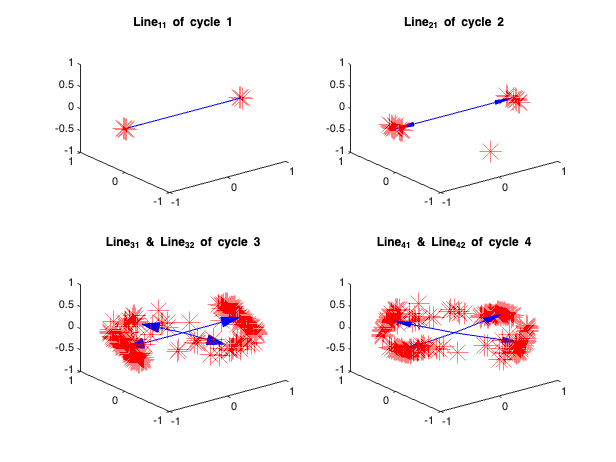

% visualize the learned weights
figure;
subplot(2,2,1)
view(3)
plot3(Z_c1(1:end-2,1),Z_c1(1:end-2,2),Z_c1(1:end-2,3),'r*','MarkerSize',20)
arrow(o,Z_c1(end-1,:),'Color','b');
arrow(o,Z_c1(end,:),'Color','b');
xlim([-1 1])
ylim([-1 1])
zlim([-1 1])
title('Line_{11} of cycle 1')

subplot(2,2,2)
view(3)
plot3(Z_c2(1:end-2,1),Z_c2(1:end-2,2),Z_c2(1:end-2,3),'r*','MarkerSize',20)
arrow(o,Z_c2(end-1,:),'Color','b');
arrow(o,Z_c2(end,:),'Color','b');
xlim([-1 1])
ylim([-1 1])
zlim([-1 1])
title('Line_{21} of cycle 2')

subplot(2,2,3)
view(3)
plot3(Z_c3(1:end-4,1),Z_c3(1:end-4,2),Z_c3(1:end-4,3),'r*','MarkerSize',20)
arrow(o,Z_c3(end-3,:),'Color','b');
arrow(o,Z_c3(end-2,:),'Color','b');
arrow(o,Z_c3(end-1,:),'Color','b');
arrow(o,Z_c3(end,:),'Color','b');
xlim([-1 1])
ylim([-1 1])
zlim([-1 1])
title('Line_{31} & Line_{32} of cycle 3')

subplot(2,2,4)
view(3)
plot3(Z_c4(1:end-4,1),Z_c4(1:end-4,2),Z_c4(1:end-4,3),'r*','MarkerSize',20)
% arrow(o,Z_c4(end-3,:),'Color','b');
% arrow(o,Z_c4(end-2,:),'Color','b');
% arrow(o,Z_c4(end-1,:),'Color','b');
% arrow(o,Z_c4(end,:),'Color','b');
for i=1:4;
    arrow(o,Z_c4(end-(i-1),:),'Color','b');
end
xlim([-1 1])
ylim([-1 1])
zlim([-1 1])
title('Line_{41} & Line_{42} of cycle 4')